%Cargar el archivo con los datos de simulación
%El archivo contiene los snapshots de la simulación
load("CYLINDER_ALL.mat", "VORTALL")
Avort = VORTALL(:,1:150);
%Empiezo haciendo el SVD
%VORTALL ya está organizado.
[U, S, V] = svd(Avort, "econ");

%Estos son los coeficientes para hacer la combinación lineal
alpha = S*V';

%U es una matriz ortogonal, es decir contiene vectores ortogonales, y
%al mismo tiempo son normales (ortonormales). También se les llama modos.
isOrthonorm = checking(U);

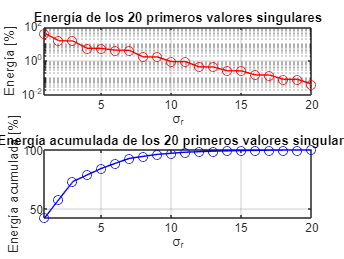

%Podemos graficar la energía contenida en cada uno de los valores
%singulares sigma

sDiagonal = diag(S);  %Construyo un vector con la diagonal de S
sSuma = sum(sDiagonal);       %Sumo el vector y guardo el valor
sSumatoria = cumsum(sDiagonal);

singularEnerg = sDiagonal/sSuma *100;  %Energía en porcentaje
singularEnergAcum = sSumatoria/sSuma *100;  %Energía en porcentaje
r = 20;     %Número de valore singulares que se usarán  


figure(1)
hold on

subplot(2,1,1)
semilogy(singularEnerg(1:r), "-or")
title(sprintf("Energía de los %d primeros valores singulares",r))
xlabel("\sigma_r")
ylabel("Energía [%]")
xlim([1 r])
grid on

subplot(2,1,2)
plot(singularEnergAcum(1:r), "-ob")
title(sprintf("Energía acumulada de los %d primeros valores singulares",r))
xlabel("\sigma_r")
ylabel("Energía acumulada [%]")
xlim([1 r])
grid on

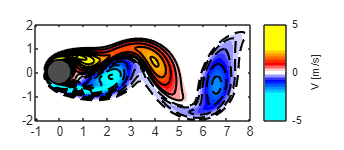

ans =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [1 1 1]
    Position: [500 300 600 260]
       Units: 'pixels'

  Show all properties


%Hacemos una primera prubea, graficando el vortice en un paso de tiempo
%específico. Aquí no hay nada de POD. Es para calibrar la función de plot
%de vórtices.
nx = 199;
ny = 449;
prueba1 = reshape(Avort(:,75),nx,ny);

figure(2)
plotVortex(prueba1)

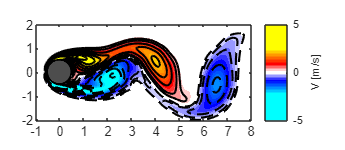

ans =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [1 1 1]
    Position: [500 300 600 260]
       Units: 'pixels'

  Show all properties


%Se toman snapshot cada 10*delta(t), y el delta(t) = 0.02 para satsifacer
%CFL
delta_t = 0.02;
t_analisis = 15;
t_index = t_analisis/(10*delta_t);

r = 10;
%Contrsuyo mis matrices usando r modos
U_red = U(:, 1:r);
alpha_red = alpha(1:r,:);

Avort_red = U_red*alpha_red(:,t_index);


figure(3)
plotVortex(reshape(Avort_red,nx,ny))

function f1 = plotVortex(Vortex)
    
    load CCcool.mat
    f1 = figure;
    vortmin = -5;
    vortmax = 5;

    Vortex(Vortex>vortmax) = vortmax;
    Vortex(Vortex<vortmin) = vortmin;

    imagesc(Vortex);
    colormap(CC);

    xticks([1 50 100 150 200 250 300 350 400 449])
    xticklabels({'-1','0','1','2','3','4','5','6','7','8'})
    yticks([1 50 100 150 199])
    yticklabels({'2','1','0','-1','-2'})
    set(gcf,'Position',[500 300 600 260])
    axis equal
    hold on

    contour(Vortex , [vortmin-0.5:0.5:-0.5 -0.250 -0.125], "--k", "LineWidth",1.4)
    contour(Vortex , [0.250 0.5:0.5:vortmax], "-k", "LineWidth",1.4)
    cb = colorbar;
    ylabel(cb,'V [m/s]');

    theta = [0:0.1:359.9]';
    x = ones(size(theta,2));
    y = ones(size(theta,2));
    x = 49+25*sind(theta);  %Son esos centro porque la imagen está escalada
    y = 99+25*cosd(theta);
    fill(x,y,[.3 .3 .3])  % place cylinder
    plot(x,y,'k','LineWidth',1.2) % cylinder boundary

end


function isOrthonorm = checking(U)
    [~,cols] = size(U);
    isOrthonorm = 2*ones(cols, cols);

    for i = 1:cols
        for j = 1:cols
            isOrthonorm(i,j) = dot(U(:,i), U(:, j));
        end
    end

end